## Q5 - Principal Component Analysis for Dimensionality Reduction

Loading the dataset in matlab,

load("../data/mnist.mat");

Converting integers to doubles and concatenating the columns of $28 \times 28$ image matrix and converting it to $28^{2} \times 1$vector,

labels = double(labels_train*1.0);
digits_vec = reshape(double(digits_train*1.0),[28*28,60000]);

Declaring,

$\texttt{count}$ - vector of size 10 to store number of times each digit appears in database

$\texttt{mu}$ - matrix of $28^{2} \times 10$ size, where each column of matrix stores mean of particular digit

$\texttt{cov}$ - matrix of $28^{2}\times28^{2}\times10$, where each $28^{2}\times28^{2}$ submatrix stores covariance matrix of each digit

count = zeros(10);
mu = zeros(28*28, 10);
cov = zeros(28*28, 28*28, 10);

Calculating sample mean $\mu$,


$$\mu = \frac{\sum_{i=1}^{N} X_{i}}{N}$$


for i=1:1:60000
    index = labels_train(i) + 1;
    mu(:, index) = mu(:, index) + digits_vec(:, i); % summing up all the values
    count(index) = count(index) + 1; % incrementing the count of each digit
end

for i=1:1:10
    mu(:, i) = mu(:, i)/count(i); % dividing the sum by count of each digit
end

Calculating sample covariance $C$,


$$C = \frac{\sum_{i=1}^{N}(X_{i}-\mu)(X_{i}-\mu)^{T}}{N}$$


for i=1:1:60000
    index = labels_train(i) + 1;
    cov(:,:,index) = cov(:,:,index) + (digits_vec(:,i)-mu(:,index))*(digits_vec(:,i)-mu(:,index))'; % summing up all values
end

for i=1:1:10
    cov(:,:, i) = cov(:,:, i)/count(i); % dividing the sum by count
end

Now that we have mean and covariance matrix, we can calculate principal modes of variance

To reduce dimensions to 84, we will need 84 eigenvectors corresponding to 84 largest eigenvalues

Let $v_{1}$, $v_{2}$, $v_{3}$, ......... $v_{84}$ be those eigenvectors.

and $X = [x_{1}$, $x_{2}$, $x_{3}$, ....... $x_{784}]^{T}$ be the image

Let $c=[c_{1}$, $c_{2}$, $c_{3}$, ....... $c_{84}]^{T}$ be the new coordinates after dimensionality reduction

Then,


$$c_{1}=X\cdot v_{1} = v_{1}^{T}X$$



$$c_{2} = X \cdot v_{2} = v_{2}^{T}X$$


.

.

.


$$c_{84} = X \cdot v_{84} = v_{84}^{T}X$$


In matrix form this is,

$c = [v_{1}$, $v_{2}$, ........ $v_{84}]^{T} X$

This calculation is done at the end of code in $\texttt{getCoordinates(.)}$ function

eigen_vecs = zeros(28*28, 84, 10);

for i=1:1:10
    [V, D] = eig(cov(:,:,i)); 
    [d, ind] = sort(diag(D), 'descend'); % sorting the eigenvalues in descending order
    eigen_vecs(:,:,i) = V(:, ind(1:84)); % getting the top 84 eigenvectors
end

• (5 points) Give an algorithm for regenerating / reconstructing the image using those 84 coordinates (and the knowledge of the designed 84-dimensional basis). For each of the ten digits (0–9), pick an image, and show the original and the reconstructed images side by side.

#### Reconstructing the image from 84 coordinates

Let $c=[c_{1}$, $c_{2}$, $c_{3}$, ....... $c_{84}]^{T}$ be the new coordinates after dimensionality reduction

Reconstructed image $I = c_{1}v_{1}+c_{2}v_{2} + ...... +c_{84}v_{84}$

In matrix form this is given by,

$I = [v_{1}$ $v_{2}$ ....... $v_{84}] c$

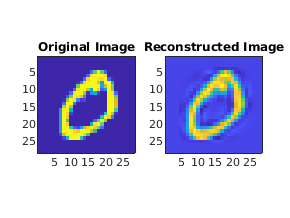

figure,
i=2;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i)); % new 84 coordinates
img = eigen_vecs(:,:, labels_train(i)+1)*c; % same as the matrix form equation given above
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28)); % reshaping and showing of original image
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28)); % reshaping and showing of reconstructed image
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

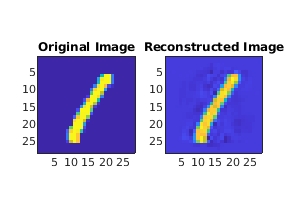


% same as above but for different digits

figure,
i=4;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

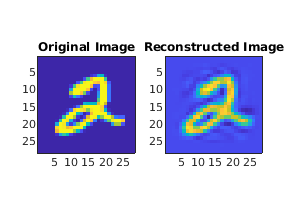


figure,
i=6;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

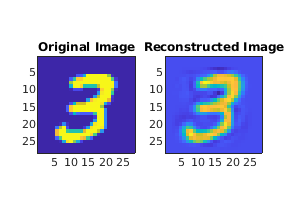


figure,
i=8;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

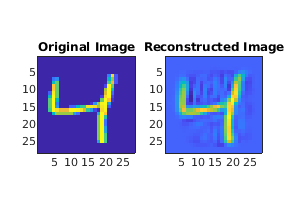


figure,
i=3;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

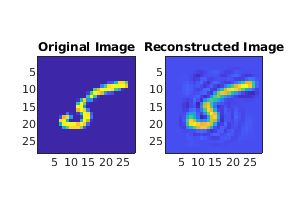


figure,
i=12;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

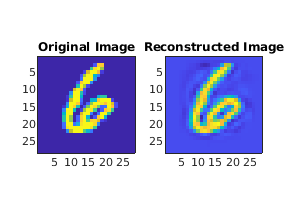


figure,
i=14;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructed Image")

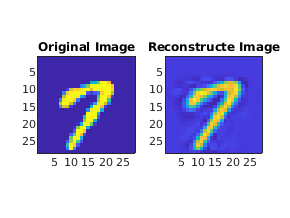


figure,
i=16;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructe Image")

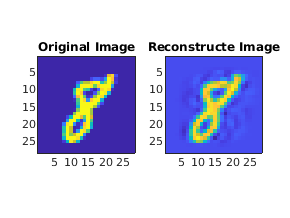


figure,
i=18;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
title("Reconstructe Image")

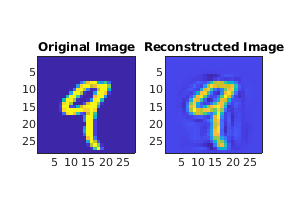


figure,
i=5;
c = getCoordinates(digits_vec(:,i), eigen_vecs, labels_train(i));
img = eigen_vecs(:,:, labels_train(i)+1)*c;
subplot(1,2,1), imagesc(reshape(digits_vec(:,i), 28, 28));
pbaspect([1,1,1]);
subplot(1,2,2), imagesc(reshape(img(:,1), 28, 28));
pbaspect([1,1,1]);

subplot(1,2,1)
title("Original Image")
subplot(1,2,2)
xlim([0.5 28.5])
ylim([0.5 28.5])
title("Reconstructed Image")

• (5 points) Write a function to compute those 84 coordinates, for each of the ten digits (0–9).

#### Calculating the coordinates

Function to calculate 84 coordinates in reduced dimensions given value of image and eigenvectors of that particular digit

function coordinates = getCoordinates(value, eigen_vecs, digit)
    coordinates = eigen_vecs(:,:,digit+1)' * value;
end